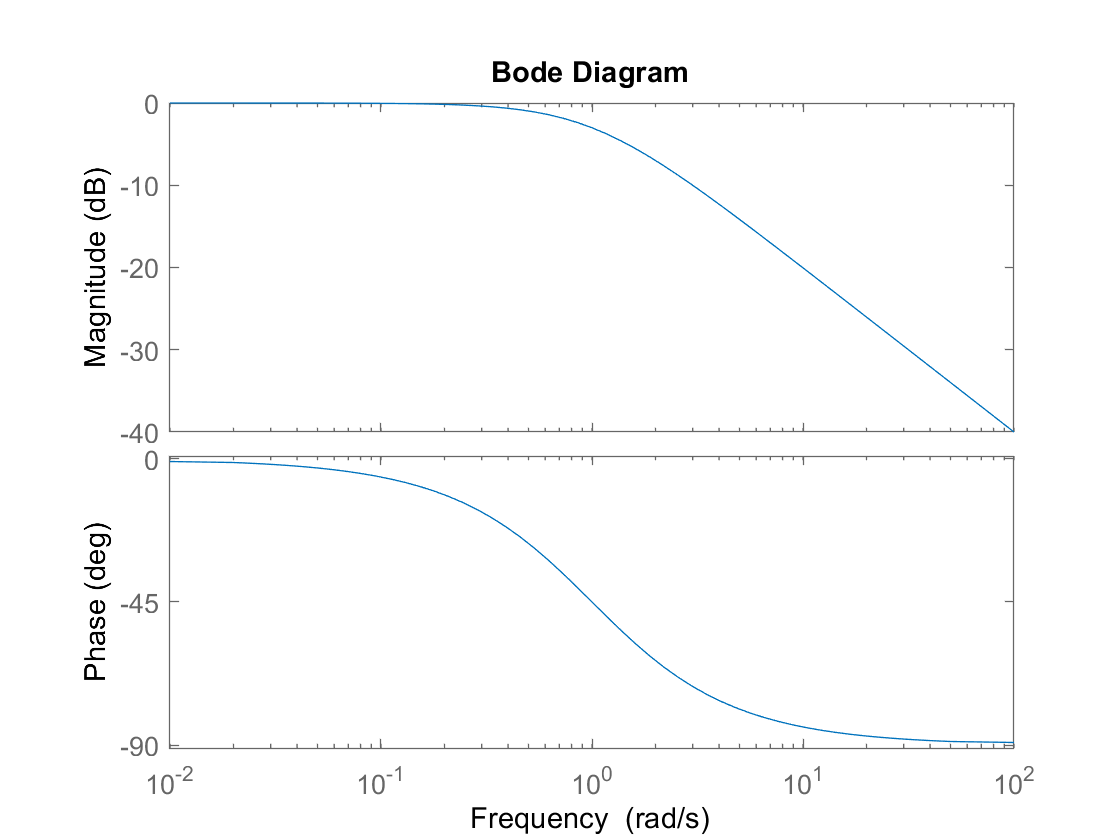

clear; clc; close all;

T = 10;         % simulation final time (seconds)
dt = 0.01;       % time step (seconds)
t = 0:dt:T;    

% Parameters: T(s) = k / (s/w + 1) from single motor model
k = 1;      
omega = 1;

s = tf('s');            
TF = k / (s / omega + 1);   % Transfer function

% step(TF);
bode(TF);

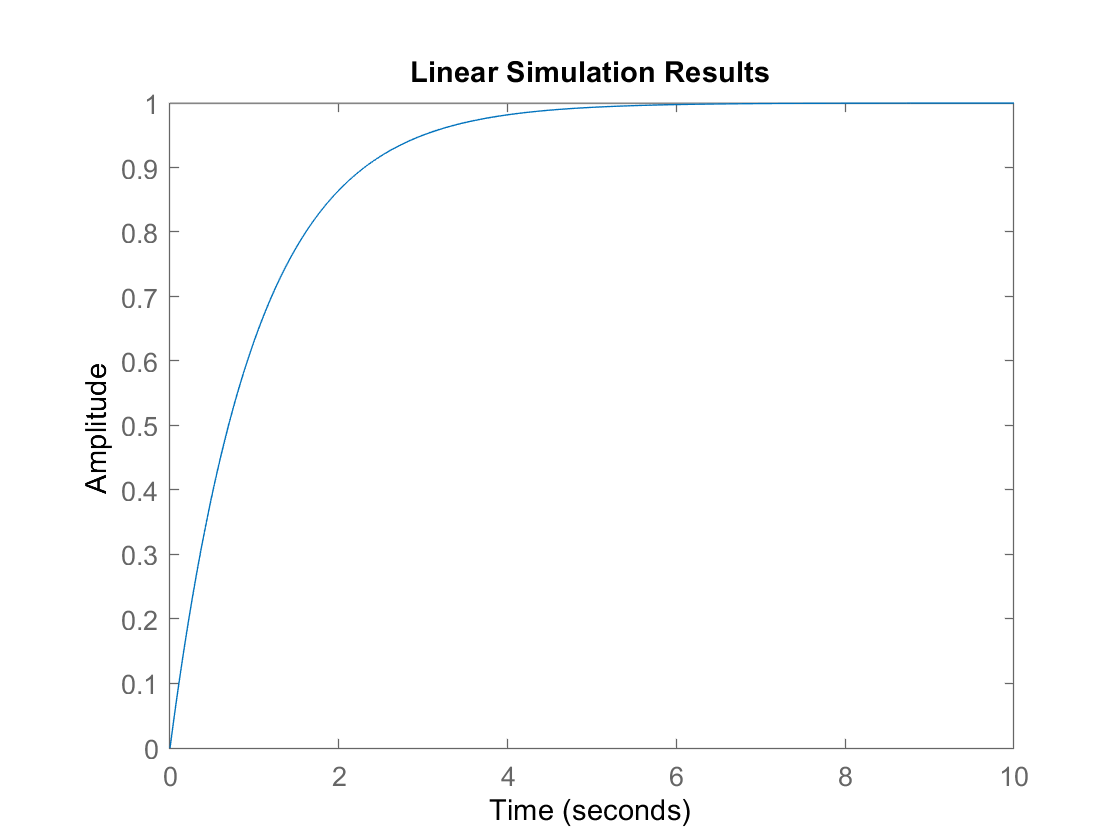

U_step = ones(1, length(t));
lsim(TF, U_step, t);

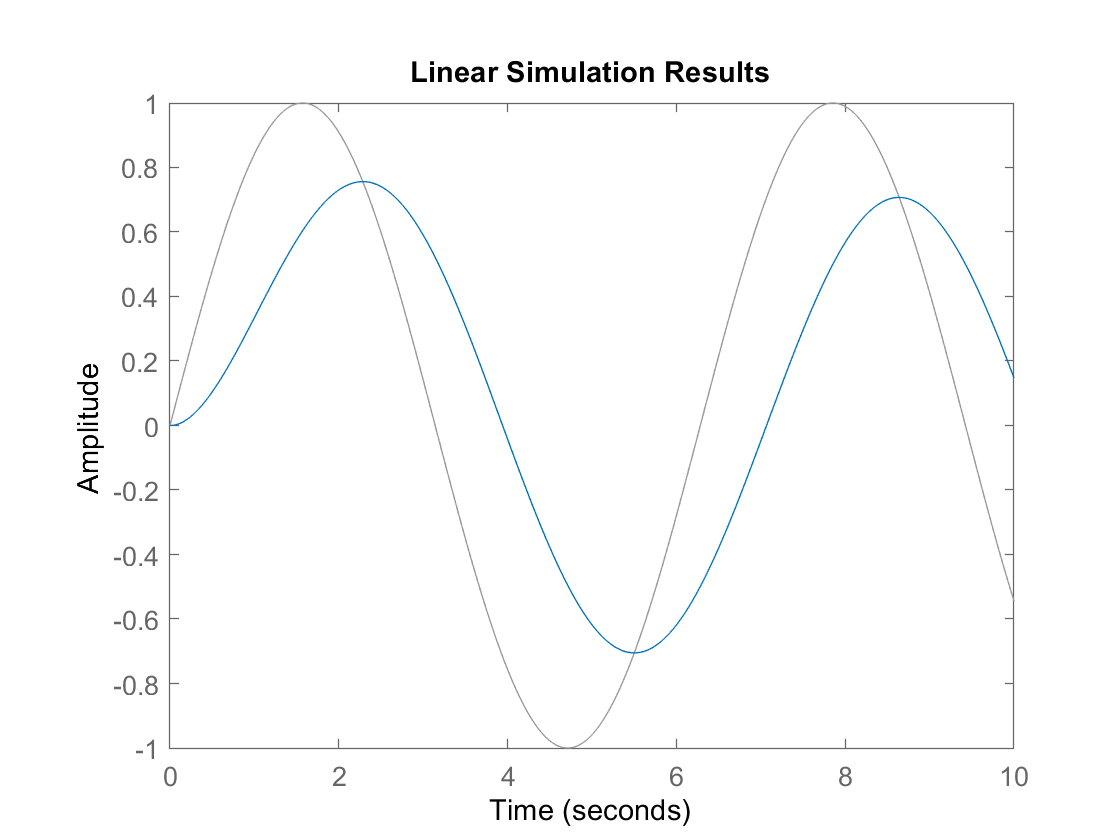

U_sin = sin(omega*t);
lsim(TF, U_sin, t);

Frequencies chosen arbitrarily

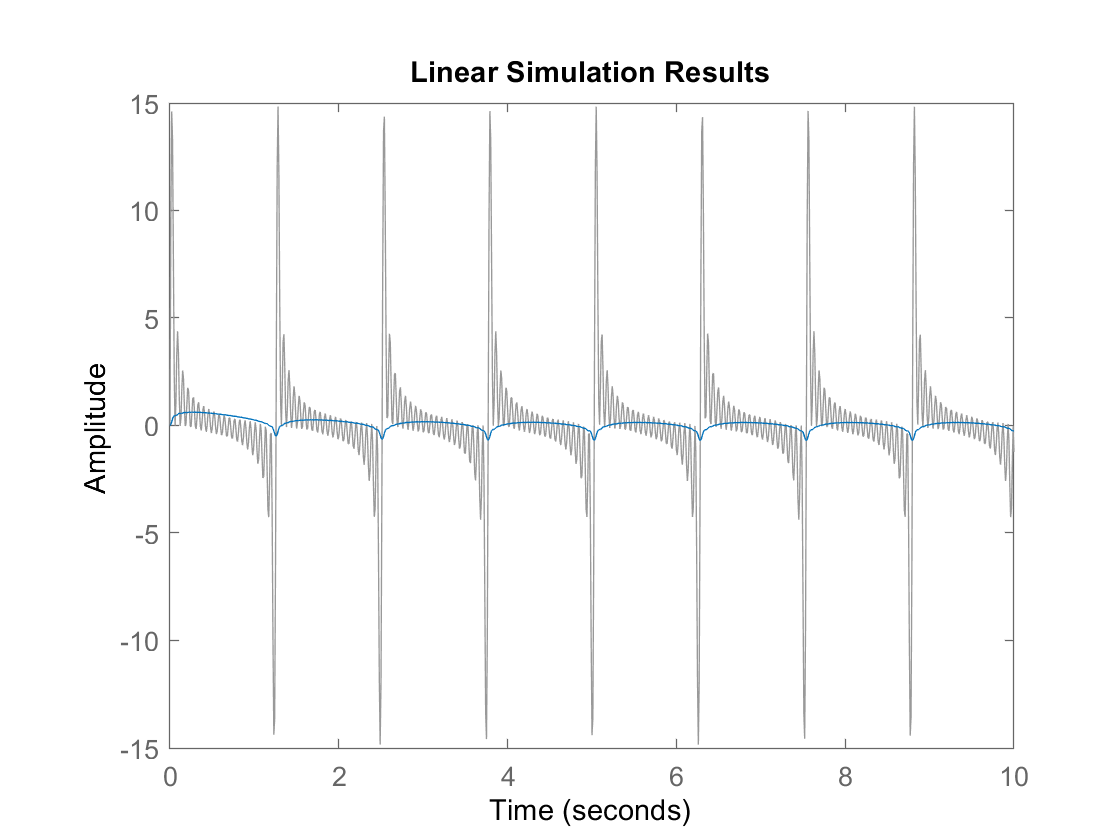

omega_range = 5:5:100;
U_range = zeros(1, length(t));

for i = 1:length(omega_range)
    U_range = U_range + sin(omega_range(i)*t);
end

lsim(TF, U_range, t);

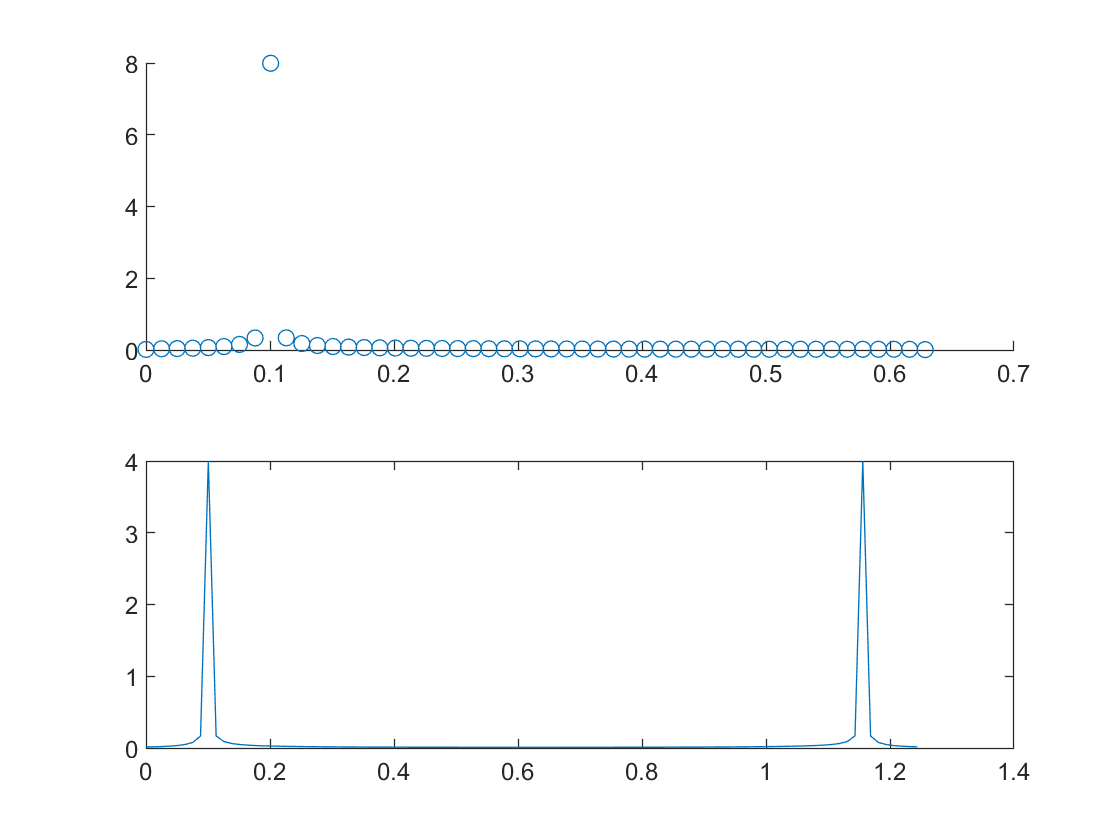

clear; clc; close all;

T = 10;
dt = 0.1;
t = 0:dt:T-dt;      % last value removed to match subsequent signal CHANGE DT TO SEE DIFFERENCES


% Input signal parameters
a = 8;              % amplitude
hertz = 1/T;    % 1/T        
omega = 2*pi*hertz; % signal frequency

% Sampling parameters
F_sampling = 2*omega;        % sampling frequency min is 2*omega CHANGE TO SEE DIFFERENCES

T_sampling = 1/F_sampling ; % sampling period
L = length(t);              % length of the signal
t_sampling = (0:L-1)*T_sampling;

% Sampling
X = a*sin(omega*t_sampling);    % signal time domain
Y = fft(X);                     % signal frequency domain

P2 = abs(Y/L);                  % two-sided spectrum
f_2 = F_sampling*(0:L-1)/L;     % frequency domain

P1 = P2(1:L/2 + 1);
P1(2:end - 1) = 2*P1(2:end -1); % one-sided spectrum
f_1 = F_sampling*(0:(L/2))/L;   % frequency domain

subplot(2,1,1)
scatter(f_1, P1)

subplot(2,1,2)
plot(f_2, P2)

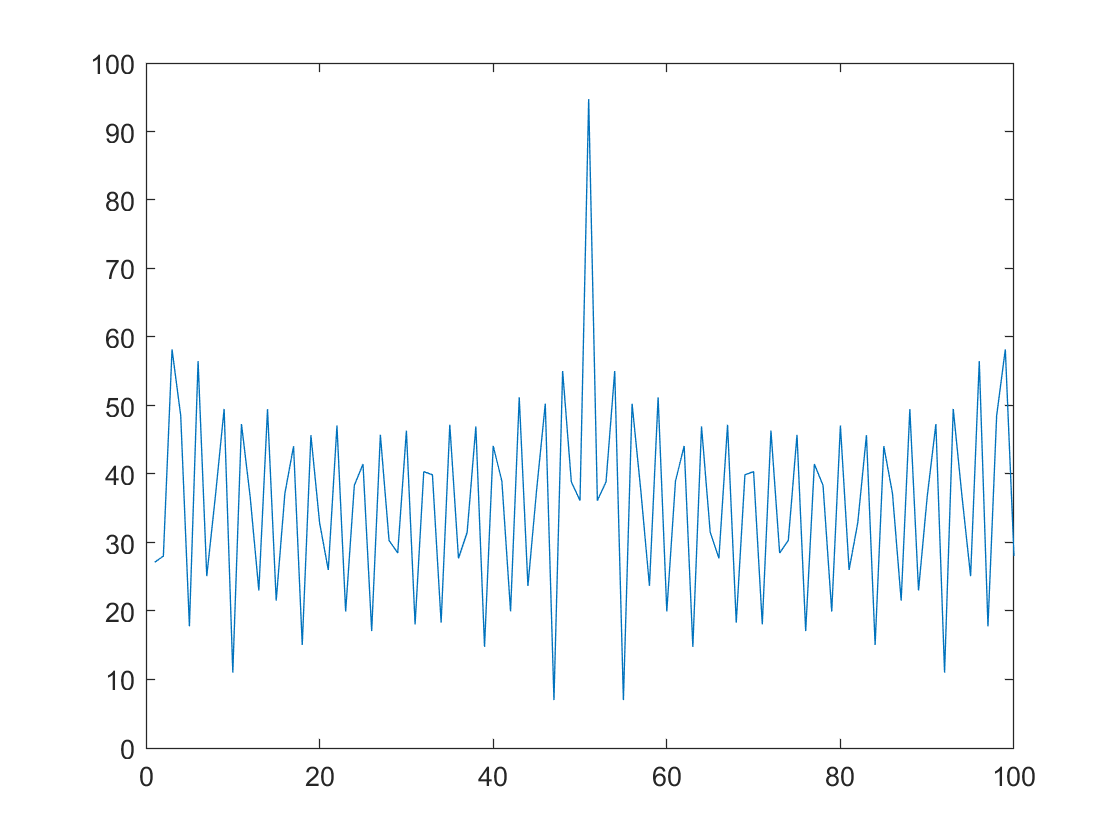

% Sampling parameters
freq_min = 2*omega;
freq_nyqist = pi/dt;

omega_range = freq_min:1:freq_nyqist;
Ut_range = zeros(1, length(t));

for i = 1:length(omega_range)
    Ut_range = Ut_range + sin(omega_range(i)*t);
end

Us_range = abs(fft(Ut_range));

% Parameters: T(s) = k / (s/w + 1) from single motor model
k = 1;    

s = tf('s');            
TF = k / (s / omega + 1);   % Transfer function

Yt_range = lsim(TF, Us_range, t);
Ys_range = abs(fft(Yt_range));

figure()
plot(Us_range)

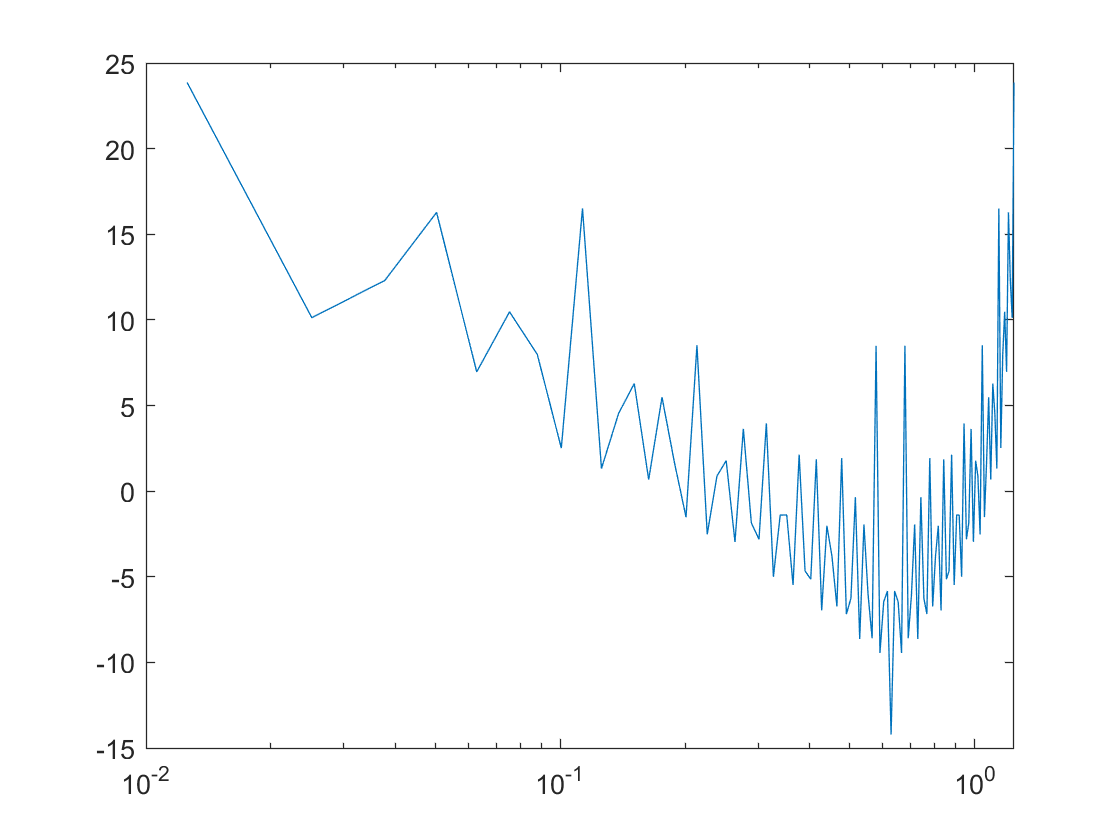


Bode_y = Ys_range./Us_range';

semilogx(f_2, 20*log10(Bode_y))